# PARAFAC tutorial

To open this page as a Matlab live script, run the command

**Notice:** The purpose of this tutorial is to demostrate the use of drEEM for PARAFAC. Here, we use a dataset cosisting of several pure compounds in arteficial seawater that are degraded in a chemostat experiment ([Sjösted et al. 2022](https://doi.org/10.3354/ame01986)). The dataset originally consisted of more than 300 samples, but we have trimmed it down to save time here. For an in-depth discussion on valid models on DOM samples from (more) *natural* environments, please refer to [Murphy et al. (2013)](https://pubs.rsc.org/en/content/articlehtml/2013/ay/c3ay41160e). 

## Toolbox setup and initiation

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;
load("parafac_tutorial_01_start.mat")

## Hold up! How does your data look?

Ready, right? Not quite! There's a simple rule that applies in computer science: [GIGO, or garbage in, garbage out](https://en.wikipedia.org/wiki/Garbage_in,_garbage_out). We can't expect a representation of our data to look reasonable if the algorithm is fed unreasonable data. We need to take a look at the data first if we have not done so already.

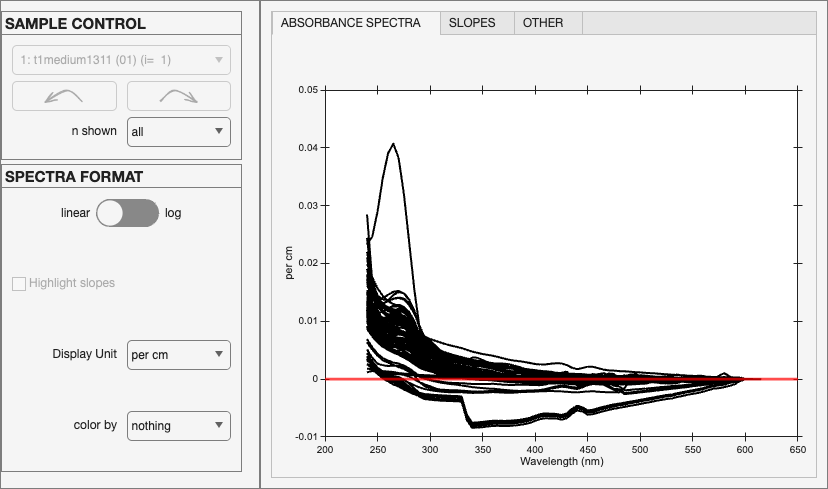

tbx.viewabsorbance(samples)

This absorbance data looks pretty bad. Luckily, the maximum absorbance per centimeter is below the threshold mentioned by Kothawala et al. (2013), so we don't necessarily have to use the data for inner-filter effect corrections. In fact, the status is already set as "deemed unnecessary" in this respect but the author of the dataset ([Sjösted et al. 2022](https://doi.org/10.3354/ame01986)):

disp(samples.status)

  drEEMstatus with properties:

    spectralCorrection: 'applied by instrument software'
         IFEcorrection: 'deemed unnecessary'
      blankSubtraction: "applied by toolbox"
     signalCalibration: "applied by toolbox (RU)"
      scatterTreatment: "applied by toolbox"
         signalScaling: 'original scale'
        absorbanceUnit: 'absorbance per cm'



Let's move on to the fluorescence:

tbx.viewspectralvariance(samples)

Consider removing the sample(s):  
If no blanks (or similar) samples are present, the issue may be samples with high fluorescence values instead.


The spectral variance of the EEMs suggests some very distinct peaks. This might not be expected for any DOM dataset, but in this case, it's ok (have a look at the study linked above). Let's look a the EEMs:

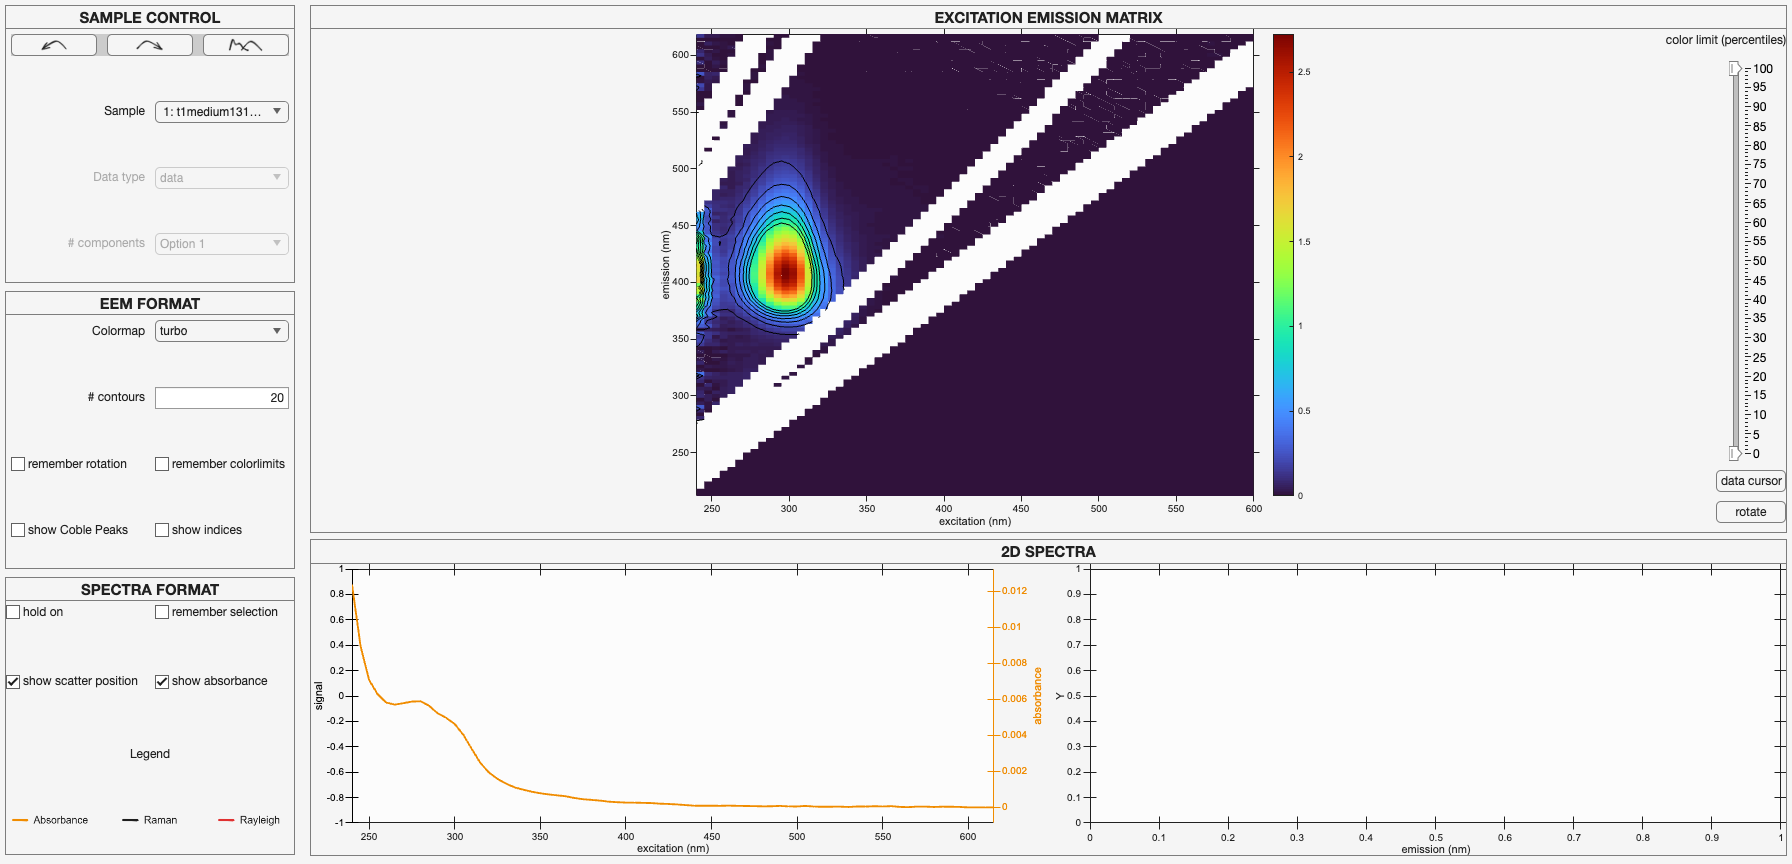

tbx.vieweems(samples)

The EEMs will have to be cut. Below about 300 nm, there is very little useful information. Either missing numbers from the scatter diagonal, or zeros inserted by [`handlescatter`](matlab:open('handlescatter.html')). Let's remember this for later. Is the dataset otherwise ready for PARAFAC?

disp(samples.status)

  drEEMstatus with properties:

    spectralCorrection: 'applied by instrument software'
         IFEcorrection: 'deemed unnecessary'
      blankSubtraction: "applied by toolbox"
     signalCalibration: "applied by toolbox (RU)"
      scatterTreatment: "applied by toolbox"
         signalScaling: 'original scale'
        absorbanceUnit: 'absorbance per cm'



For example, the fluoresccence signals should be calibrated in some way (the toolbox supports Raman Units). Scatter should be removed. Good news is that the toolbox actually checks for you (i.e. you would get error messages when appropriate)!

After you browsed through the data above and agree that the samples look reasonable, we can proceed.

## Preliminary test models & dataset refinement

Remember the issue with short emission wavelengths? Let's fix that with [`subdataset`](matlab:open('subdataset.html')).

samples=tbx.subdataset(samples,outEm=samples.Em<300);

This call deletes emission below 300 nm. That should take care of the issue for us. Let's try some models with relatively high convergence criterion and few starts. Since we don't know how many components are appropriate, we fit what is probably too few and what might be too many.

samples=tbx.fitparafac(samples,"fitoverall",f=2:7,convergence=1e-4,starts=2);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 10 workers.
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         2
Convergence criterion:           0.0001
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               15.336
-----
  
# 001 done | #iter: 3    | time: 00:04 | it/sec: 1
# 002 done | #iter: 3    | time: 00:04 | it/sec: 1
# 003 done | #iter: 5    | time: 00:04 | it/sec: 1
# 004 done | #iter: 13   | time: 00:04 | it/sec: 3
# 005 done | #iter: 4    | time: 00:04 | it/sec: 1
# 006 done | #iter: 32   | time: 00:04 | it/sec: 8
# 007 done | #iter: 34   | time: 00:05 | it/sec: 8
# 008 done | #iter: 33   | time: 00:05 | it/sec: 8
# 009 done | #iter: 53   | time: 00:05 | it/sec: 13
# 010 done | #iter: 46   | time: 00:05 | it/sec: 11
# 011 done | #iter: 18   |

tbx.viewmodels(samples)

Based on the first overview plot, it seems like 2-6 components is appropriate since we get high core consistencies whereas after 6 components, the increase in explained variance is low and the core consistency drops.

If we skip to the "Scores & loadings" tab in the GUI figure, 2-4 component models look nice and systematic. But the 5th component is quite noisy with a sharp increase in loadings toward the UV. The "Score correlation" tab shows us that the components are not very badly autocorrelated. That's great news.

samples=tbx.addcomment(samples,"first outliertest. Seems quite ok. Looks like max 6C is appropriate.");

You can see that the first step was to fit lots of components with few starts to each and use a high convergence criterion. This used to be called "outliertest".

The conclusion from these models are that the data seems to produce reasonable PARAFAC models. Let's reduce the convergence criterion and use a few more models ("starts") to get a more firm idea. But we can skip 2 and 3 component models (they won't get deleted though).

See how I left myself a comment in the dataset? This way, you can retrace your steps and document your decision making process.

samples=tbx.fitparafac(samples,"fitoverall",f=4:6,convergence=1e-6,starts=4);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               15.336
-----
  
# 001 done | #iter: 83   | time: 00:03 | it/sec: 29
# 002 done | #iter: 84   | time: 00:04 | it/sec: 26
# 003 done | #iter: 70   | time: 00:03 | it/sec: 30
# 004 done | #iter: 68   | time: 00:03 | it/sec: 24
# 005 done | #iter: 68   | time: 00:03 | it/sec: 33
# 006 done | #iter: 82   | time: 00:03 | it/sec: 28
# 007 done | #iter: 63   | time: 00:03 | it/sec: 22
# 008 done | #iter: 69   | time: 00:03 | it/sec: 25
# 009 done | #iter: 364  | time: 00:04 | it/sec: 96
# 010 done | #iter: 653  | time: 00:05 | it/sec: 149
# 011 done | #iter: 70   | time: 00:02 | it/sec: 37
# 012 done | #iter: 165  | time

tbx.viewmodels(samples)
samples=tbx.addcomment(samples,"Those last few components seem noisy");

When we run a couple more models with lower convergence, it seems the models still look good. But the loadings of the 5th and 6th component are still noisy. Since the noise is often associated with short UV excitation wavelengths, we could try to delete some of the UV excitation to improve the situation:

samples=tbx.subdataset(samples,outEx=samples.Ex<250);

A call to subdataset with pre-existing models results in their deletion.


samples=tbx.addcomment(samples,"Deleted short-UV excitation to reduce noise in the dataset");

Let's fit the models again:

samples=tbx.fitparafac(samples,"fitoverall",f=4:7,convergence=1e-6,starts=4);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [4  5  6  7]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               15.245
-----
  
# 001 done | #iter: 91   | time: 00:04 | it/sec: 29
# 002 done | #iter: 42   | time: 00:03 | it/sec: 15
# 003 done | #iter: 56   | time: 00:03 | it/sec: 19
# 004 done | #iter: 21   | time: 00:03 | it/sec: 7
# 005 done | #iter: 97   | time: 00:04 | it/sec: 32
# 006 done | #iter: 96   | time: 00:03 | it/sec: 32
# 007 done | #iter: 77   | time: 00:04 | it/sec: 25
# 008 done | #iter: 69   | time: 00:04 | it/sec: 22
# 009 done | #iter: 87   | time: 00:04 | it/sec: 28
# 010 done | #iter: 257  | time: 00:04 | it/sec: 73
# 011 done | #iter: 83   | time: 00:02 | it/sec: 45
# 012 done | #iter: 406  | tim

tbx.viewmodels(samples)

With the noise reduced, the 5, 6, and 7-component model now show a strange component. Take a look at the loadings and leverages plot specifically:

tbx.viewmodels(samples,"Loadings & leverages",6)

It might be hard to see, but the sample with data identifier 4 sticks out massivly.

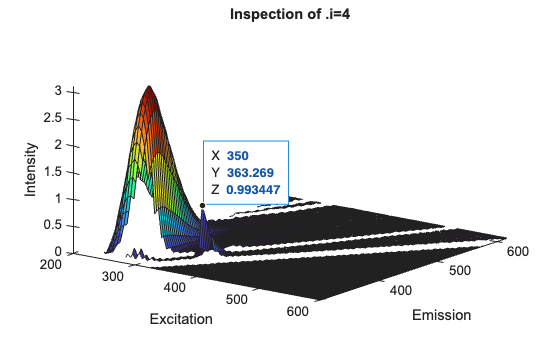

h=surface(samples.Ex,samples.Em,squeeze(samples.X(samples.i==4,:,:)));
view(397,25),datatip(h,350,363,0.993);
xlabel('Excitation'),ylabel('Emission'),zlabel('Intensity'),title('Inspection of .i=4')

The above written code is just there to show the issue in this tutorial. You should use vieweems to navigate to this sample and you'd see the exact same issue appearing.

This is a job for [`zapnoise`](matlab:open('zapnoise.html')). The data highlighted above does not represent fluorescence but is likely the consequence of a bubble of air or a small particle getting trapped in the light path during the measurement for a short period of time. This can cause the temporary appearance of scatter in the entire EEM. Since PARAFAC tries to minimize the error and is given enough freedom starting at 6 components, the feature rivals the importance of the real signals at that point. If taken away, the model is likely going to focus on the real signals once more.

**Note: In this situation, the solution is not to settle for the last model with reasonable components. Instead, fix the issue in the data and try again!**

samples = tbx.zapnoise(samples,samples.i==4,[],[340 360]);

A call to zapnoise with pre-existing models results in their deletion.


samples = tbx.addcomment(samples,'Removed scatter that impacted models.');

Now, we should test if this action will lead to better models.

samples=tbx.fitparafac(samples,"fitoverall",f=4:7,convergence=1e-6,starts=4);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [4  5  6  7]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               15.312
-----
  
# 001 done | #iter: 54   | time: 00:02 | it/sec: 29
# 002 done | #iter: 49   | time: 00:02 | it/sec: 30
# 003 done | #iter: 83   | time: 00:03 | it/sec: 37
# 004 done | #iter: 49   | time: 00:02 | it/sec: 28
# 005 done | #iter: 112  | time: 00:03 | it/sec: 50
# 006 done | #iter: 84   | time: 00:03 | it/sec: 37
# 007 done | #iter: 77   | time: 00:03 | it/sec: 34
# 008 done | #iter: 91   | time: 00:03 | it/sec: 41
# 009 done | #iter: 336  | time: 00:04 | it/sec: 110
# 010 done | #iter: 378  | time: 00:04 | it/sec: 114
# 011 done | #iter: 357  | time: 00:04 | it/sec: 91
# 012 done | #iter: 91   | 

tbx.viewmodels(samples,"Loadings & leverages",6) % The 2nd and 3rd input are only there for the sake of figures in the tutorial

Yes, zapping the noise seems to have improved the situation. Also, the ealier removal of the noisy part of the excitation spectrum has led finally led to the desired improvement (which we can see now). I'll leave a comment in the dataset.

samples=tbx.addcomment(samples,"Subsetting and zapping helped a lot. 5-6 component models have less noisy components.");

Notice how there are no loadings in the excitation past 500nm? We could delete this part of the EEM. It contains no useful information and just costs us time, storage space, and might actually make the situation worse if noise is present. Doing so, we need to refit the models.

samples=tbx.subdataset(samples,outEx=samples.Ex>450);

A call to subdataset with pre-existing models results in their deletion.


samples=tbx.addcomment(samples,"Deleted long excitation to reduce dataset size");
samples=tbx.fitparafac(samples,"fitoverall",f=4:7,convergence=1e-6,starts=4);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [4  5  6  7]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               17.212
-----
  
# 001 done | #iter: 49   | time: 00:02 | it/sec: 43
# 002 done | #iter: 63   | time: 00:02 | it/sec: 47
# 003 done | #iter: 56   | time: 00:02 | it/sec: 40
# 004 done | #iter: 61   | time: 00:02 | it/sec: 43
# 005 done | #iter: 84   | time: 00:02 | it/sec: 58
# 006 done | #iter: 76   | time: 00:02 | it/sec: 53
# 007 done | #iter: 119  | time: 00:02 | it/sec: 77
# 008 done | #iter: 70   | time: 00:02 | it/sec: 51
# 009 done | #iter: 234  | time: 00:02 | it/sec: 127
# 010 done | #iter: 299  | time: 00:03 | it/sec: 148
# 011 done | #iter: 101  | time: 00:02 | it/sec: 89
# 012 done | #iter: 66   | 

tbx.viewmodels(samples,"Loadings & leverages",6) % The 2nd and 3rd input are only there for the sake of figures in the tutorial

Those models look quite good now. At this point, we could move on and inspect residuals. But have you noticed that we quitely assumed some default options for PARAFAC? One of those default options is the nonnegativity constraint. This option is enabled by default since it fits the analytical principle well and constraining the model in this way also mitigates something known as [two-factor degeneracy](https://doi.org/10.1016/S0169-7439(97)00033-6). But a well-behaved dataset should theoretically not need this constraint. If the dataset still produces nice models, you know you're in good shape. Let's try:

test=tbx.fitparafac(samples,"fitoverall", ...
    f=4:7,convergence=1e-6,starts=15,constraints="unconstrained");

Notice: Automatically changed from the default toolbox to nway
Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  nway
Parallelization:                 true
Models with components:          [4  5  6  7]
Number of random starts:         15
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      unconstrained
% missing numbers:               17.212
-----
  
# 001 done | #iter: 63   | time: 00:06 | it/sec: 12
# 002 done | #iter: 63   | time: 00:06 | it/sec: 12
# 003 done | #iter: 106  | time: 00:06 | it/sec: 20
# 004 done | #iter: 258  | time: 00:09 | it/sec: 29
# 005 done | #iter: 142  | time: 00:06 | it/sec: 26
# 006 done | #iter: 258  | time: 00:09 | it/sec: 30
# 007 done | #iter: 150  | time: 00:07 | it/sec: 25
# 008 done | #iter: 266  | time: 00:09 | it/sec: 31
# 009 done | #iter: 106  | time: 00:06 | it/sec: 21
# 010 done | #iter: 63   | time: 00:06 | it/sec: 12
# 012

tbx.viewmodels(test)

Take a look at these models. Overall, the loadings look very reasonable and mostly nonnegative even without the constraint being enforced. The core consistency is interestingly showing a considerable drop for the 6-component model, whereas for the constrained models it was slightly higher.

Together, these data give us a lot of evidence for which model (i.e. how many components) is appropriate. The one topic we have not yet discussed are residuals.

So let's take a look. Switch to the "SSE" tab in the [`viewmodels`](http://viewmodels.html) app. That seems to suggest that the last component that removes spectrally structured error is the 5-component model. After that,the leftover signals might be more related to bad measurements, but we'd need a detailed analysis for this. This is where [`viewdmr`](matlab:open('viewdmr.html')) comes in handy. Let's switch to the nonnegative models again and take a look at the 5-component model:

tbx.viewdmr(samples,5)

The residuals look quite ok for the that model. Of course, there are samples where the model definitly does not fit perfectly. But keep in mind that the app by default zooms in to 10% of the sample's signal intensity, so residuals appear worse than they actually are when scaling by the original sample's intensity. 

Again, the residuals seem to look ok for the 5-6 component models. Let's run those models with low convergence and many starts:

samples=tbx.fitparafac(samples,"fitoverall",f=5:6,convergence=1e-8,starts=30);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [5  6]
Number of random starts:         30
Convergence criterion:           1e-08
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               17.212
-----
  
# 001 done | #iter: 217  | time: 00:03 | it/sec: 100
# 002 done | #iter: 217  | time: 00:03 | it/sec: 98
# 003 done | #iter: 217  | time: 00:03 | it/sec: 100
# 004 done | #iter: 217  | time: 00:03 | it/sec: 93
# 005 done | #iter: 217  | time: 00:03 | it/sec: 93
# 006 done | #iter: 217  | time: 00:03 | it/sec: 95
# 007 done | #iter: 217  | time: 00:03 | it/sec: 97
# 008 done | #iter: 224  | time: 00:03 | it/sec: 105
# 009 done | #iter: 217  | time: 00:03 | it/sec: 99
# 010 done | #iter: 217  | time: 00:03 | it/sec: 94
# 011 done | #iter: 217  | time: 00:03 | it/sec: 99
# 012 done | #iter: 217  | time

tbx.viewmodels(samples)

There were quite a few 6 component models that hit the limit for number of iterations. Let's increase the number to get more models to properly converge. Notice that I only repeat the 6-component models (in my run, this was the only model to be affected).

samples=tbx.fitparafac(samples,"fitoverall", ...
    f=6,convergence=1e-8,starts=30, ...
    maxIteration=5000);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [6]
Number of random starts:         30
Convergence criterion:           1e-08
Maximum number of iterations:    5000
Constraint:                      nonnegativity
% missing numbers:               17.212
-----
  
# 002 done | #iter: 454  | time: 00:05 | it/sec: 106
# 005 done | #iter: 678  | time: 00:06 | it/sec: 126
# 008 done | #iter: 1001 | time: 00:07 | it/sec: 157
# 010 done | #iter: 707  | time: 00:06 | it/sec: 139
# 007 done | #iter: 1288 | time: 00:09 | it/sec: 148
# 012 done | #iter: 553  | time: 00:05 | it/sec: 127
# 015 done | #iter: 663  | time: 00:05 | it/sec: 140
# 004 done | #iter: 5000 | time: 00:29 | it/sec: 174
# 006 done | #iter: 5000 | time: 00:30 | it/sec: 168
# 003 done | #iter: 5000 | time: 00:31 | it/sec: 166
# 001 done | #iter: 5000 | time: 00:31 | it/sec: 165
# 009 done | #iter: 5000 |

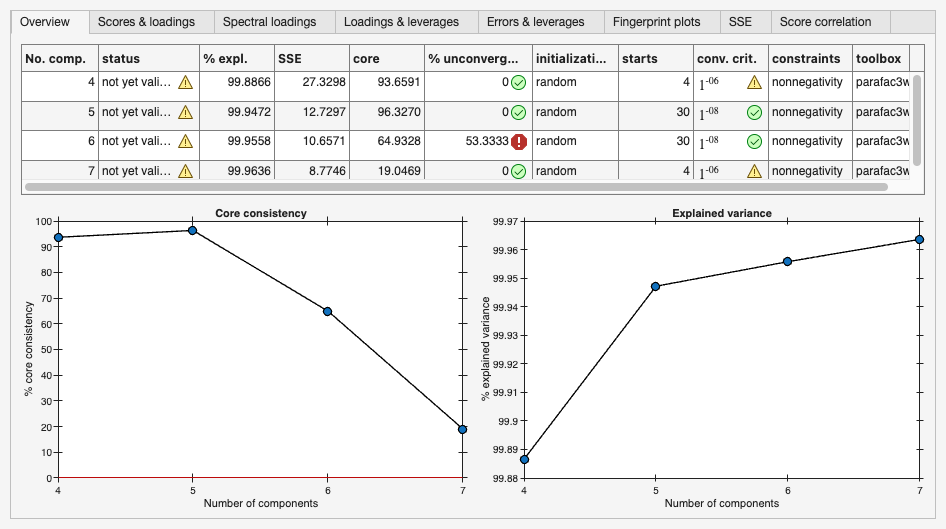

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"6-C model hits iterations limit, even after allowing for more.");

Seems like there are still quite a few models that came back hitting the maximum. That suggests that this is a tricky model to fit for the algorithm. I left myself a comment on this, since it likely indicates that the 6-component model (and thus maybe also the 7C model) is no longer appropriate. Remember that the 6-component model also had a low core consistency when it was run unconstrained? More evidence accumulates to tell us about the most appropriate model.

At this point, we can sum up before we attempt a validation. The core consistency was high up to 6 components when constrained and up to 5 when unconstrained. Explained variance did not improve from the 5 to the 6 component model. Residuals are not completely random in either, but look ok for both. On the extreme ends, 4 components are too few and 7 is definitely too much (core consistency drop!).

From all of this, we could identify the 5 component model as the best representation. So let's attempt a model validation.

## Splitvalidation

samples=tbx.splitdataset(samples,"blind");

The default call to splitdataset performs a split into two datasets via an alternating assignment into split 1 or two without considering metadata ("`blind`"). Here, we have very view samples and assigning the splits in this way also doesn't bias our split datasets in any way. However, this might not be the case in your dataset. 

One could split the dataset by type, like this (though this makes no sense here because some types only have one sample):

demo=tbx.splitdataset(samples,"byMetadata","metadataColumn",'type');

This creates sevearl datasets, and some datasets with very few samples. So this approach would not lead to robust models in all likelyhood.

disp(['Number of samples in the metadata splits: ',num2str([demo.split(:).nSample])])

Number of samples in the metadata splits: 41   1  45   2


clearvars demo % Let's keep the workspace tidy

Just keep in mind that the [`splitdataset`](matlab:open('splitdataset.html')) function can help you reorganize your datasets by metadata and is not just there as a tool to make 2 random splits for splitvalidation.

***The validation is ******your****** safety check and you should perform it in a way that critically inspects your analysis. Have a look at the ***[***documentation***](matlab:open('splitdataset.html'))*** here.***

Next, we use the same function from before, but by specifiying `mode='split'`. This way, the function looks only at the split datasets, not the overall, original dataset. Though those models are still saved in the dataset as well.

samples=tbx.fitparafac(samples,"fitsplits", ...
    f=5:6,convergence=1e-8, ...
    starts=50);

Existing parallel pool of 10 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [5  6]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               17.212
-----
  
# 001 done | #iter: 217  | time: 00:02 | it/sec: 206
# 002 done | #iter: 364  | time: 00:02 | it/sec: 305
# 003 done | #iter: 217  | time: 00:02 | it/sec: 195
# 004 done | #iter: 217  | time: 00:02 | it/sec: 216
# 005 done | #iter: 252  | time: 00:02 | it/sec: 227
# 006 done | #iter: 217  | time: 00:02 | it/sec: 194
# 007 done | #iter: 224  | time: 00:02 | it/sec: 224
# 008 done | #iter: 217  | time: 00:02 | it/sec: 201
# 009 done | #iter: 217  | time: 00:02 | it/sec: 207
# 010 done | #iter: 231  | time: 00:02 | it/sec: 211
# 011 done | #iter: 224  | time: 00:01 | it/sec: 244
# 012 done | #iter: 217

All models finsished. Calculating model metrics ...
 
Done. This took: 1.06min. Iterations per second (parallelized): 3575
 
 Successful validation  (5-compnent model)
 Failed validation  (6-compnent model)


You can see from the final console output that the function also already performs spectral comparisons to let you know if the validation worked. The next call really only serves as visual output for ourselves.

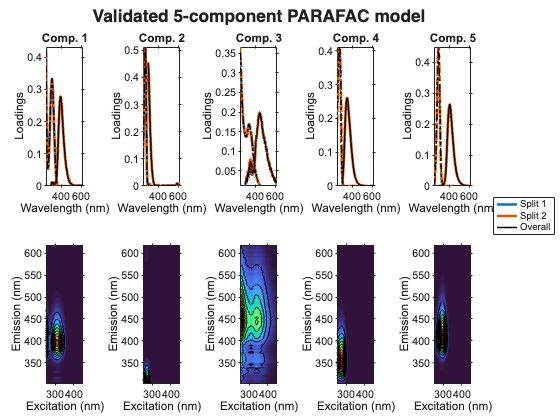

 
Overall Result= Validated for all comparisons


tbx.viewsplitvalidation(samples,5);

Let's save our hard work.

save('tutorial_parafac_modelled.mat',"samples","samples")
%close all force % Clean up with all these UI figure windows present

For the sake of this tutorial, we now move on to the next step. That's data export. Since it's a topic in itself, [you can find this in the Data export tutorial](matlab:open('./tutorial_export_01.html')).